import RoboticaBiblioteca.*

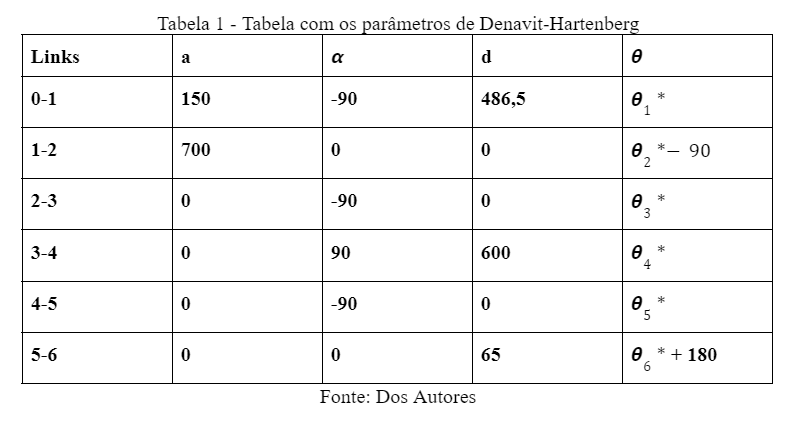

### VALIDAÇÃO 1

theta1 = 0;
theta2 = 0;
theta3 = 0;
theta4 = 0;
theta5 = 0;
theta6 = 0;

DH = [150 -90 486.5 theta1;
      700 0 0 theta2-90;
      0 -90 0 theta3;
      0 90 600 theta4;
      0 -90 0 theta5;
      0 0 65 theta6+180];
[H06, Alc] = MatProgDenavit(DH);

A01 = 
    1.0000         0         0  150.0000
         0         0    1.0000         0
         0   -1.0000         0  486.5000
         0         0         0    1.0000

A12 = 
     0     1     0     0
    -1     0     0  -700
     0     0     1     0
     0     0     0     1

A23 = 
     1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1

A34 = 
     1     0     0     0
     0     0    -1     0
     0     1     0   600
     0     0     0     1

A45 = 
     1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1

A56 = 
    -1     0     0     0
     0    -1     0     0
     0     0     1    65
     0     0     0     1



q = [1;1;1;1;1;1];
[Velocidade, J] = velJacob(Alc,q,'RRRRRR',true)

Z0 = 
     0
     0
     1

O0 = 
     0
     0
     0

Z1 = 
     0
     1
     0

O1 = 
  150.0000
         0
  486.5000

Z2 = 
     0
     1
     0

O2 = 
   1.0e+03 *

    0.1500
         0
    1.1865

Z3 = 
     1
     0
     0

O3 = 
   1.0e+03 *

    0.1500
         0
    1.1865

Z4 = 
     0
     1
     0

O4 = 
   1.0e+03 *

    0.7500
         0
    1.1865

Z5 = 
     1
     0
     0

O5 = 
   1.0e+03 *

    0.7500
         0
    1.1865

O6 = 
   1.0e+03 *

    0.8150
         0
    1.1865



Velocidade =          700
         815
       -1395
           2
           3
           1


J =      0   700     0     0     0     0
   815     0     0     0     0     0
     0  -665  -665     0   -65     0
     0     0     0     1     0     1
     0     1     1     0     1     0
     1     0     0     0     0     0


### VALIDAÇÃO 2

theta1 = 0;
theta2 = 22.57;
theta3 = 0;
theta4 = -114.75;
theta5 = 60.32;
theta6 = 0;

DH = [150 -90 486.5 theta1;
      700 0 0 theta2-90;
      0 -90 0 theta3;
      0 90 600 theta4;
      0 -90 0 theta5;
      0 0 65 theta6+180];
[H06, Alc] = MatProgDenavit(DH)

A01 = 
    1.0000         0         0  150.0000
         0         0    1.0000         0
         0   -1.0000         0  486.5000
         0         0         0    1.0000

A12 = 
    0.3838    0.9234         0  268.6683
   -0.9234    0.3838         0 -646.3879
         0         0    1.0000         0
         0         0         0    1.0000

A23 = 
     1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1

A34 = 
   -0.4187         0   -0.9081         0
   -0.9081         0    0.4187         0
         0    1.0000         0  600.0000
         0         0         0    1.0000

A45 = 
    0.4952         0   -0.8688         0
    0.8688         0    0.4952         0
         0   -1.0000         0         0
         0         0         0    1.0000

A56 = 
    -1     0     0     0
     0    -1     0     0
     0     0     1    65
     0     0     0     1



H06 = 	1.0e+03 *

   -0.0007   -0.0003    0.0006    1.0115
   -0.0004   -0.0004   -0.0008   -0.0513
    0.0005   -0.0008    0.0001    0.9121
         0         0         0    0.0010


Alc = 1×6 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


q = [1;1;1;1;1;1];
[Velocidade, J] = velJacob(Alc,q,'RRRRRR',true)

Z0 = 
     0
     0
     1

O0 = 
     0
     0
     0

Z1 = 
     0
     1
     0

O1 = 
  150.0000
         0
  486.5000

Z2 = 
     0
     1
     0

O2 = 
   1.0e+03 *

    0.4187
         0
    1.1329

Z3 = 
    0.9234
         0
   -0.3838

O3 = 
   1.0e+03 *

    0.4187
         0
    1.1329

Z4 = 
   -0.3486
   -0.4187
   -0.8386

O4 = 
  972.7151
         0
  902.6008

Z5 = 
    0.5968
   -0.7890
    0.1458

O5 = 
  972.7151
         0
  902.6008

O6 = 
   1.0e+03 *

    1.0115
   -0.0513
    0.9121



Velocidade = 	1.0e+03 *

    0.1894
    0.9586
   -1.4676
    0.0012
    0.0008
   -0.0001


J = 	1.0e+03 *

    0.0513    0.4256   -0.2208   -0.0197   -0.0470   -0.0000
    1.0115         0         0   -0.0236   -0.0292   -0.0000
         0   -0.8615   -0.5928   -0.0474    0.0341   -0.0000
         0         0         0    0.0009   -0.0003    0.0006
         0    0.0010    0.0010         0   -0.0004   -0.0008
    0.0010         0         0   -0.0004   -0.0008    0.0001



M = coef3(0,80,10)

M =          0
    0.0000
    2.4000
   -0.1600


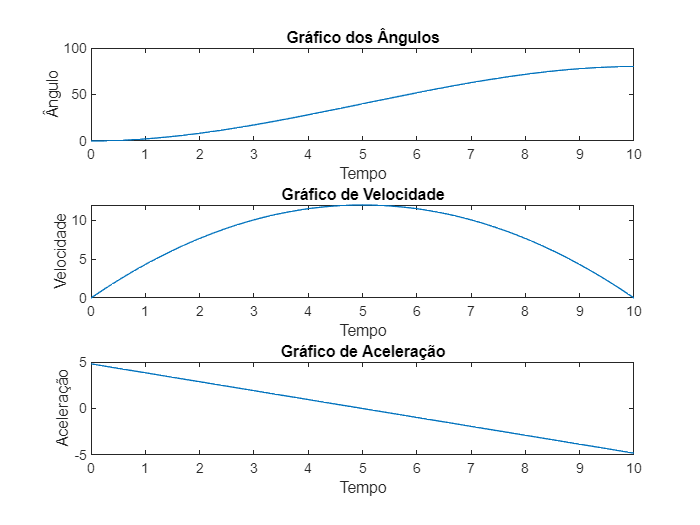

graf3ordPosVelAcel(M,10)

M = coef3(0,45,10)

M =          0
   -0.0000
    1.3500
   -0.0900


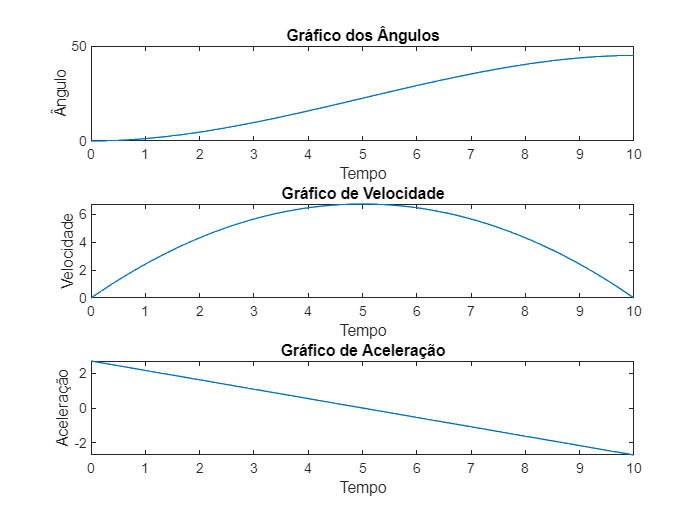

graf3ordPosVelAcel(M,10)

M = coef3(0,20,10)

M =          0
    0.0000
    0.6000
   -0.0400


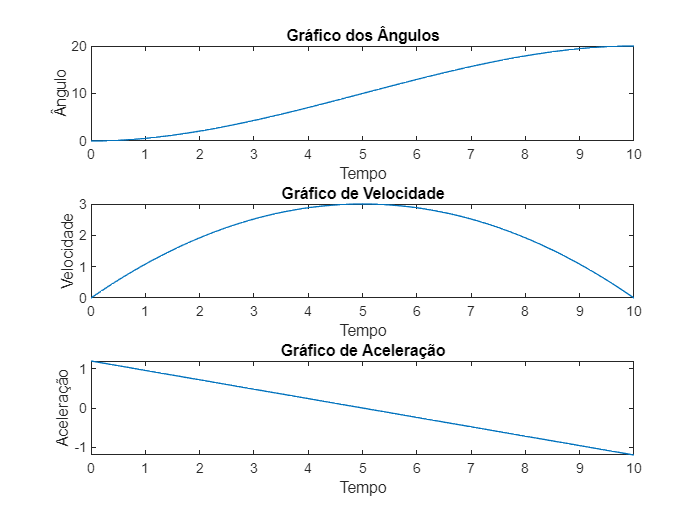

graf3ordPosVelAcel(M,10)

M = coef5(0,100,10,0)

M =          0
         0
         0
    1.0000
   -0.1500
    0.0060


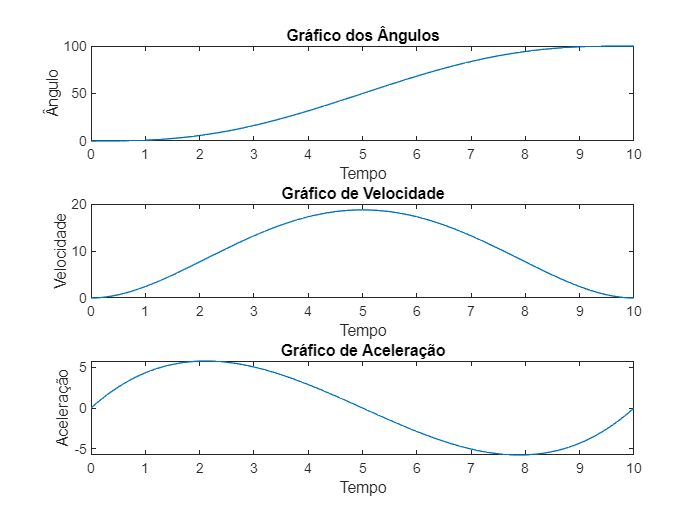

graf5ordPosVelAcel(M,10)

M = coef5(0,30,10,3)

M =          0
         0
    1.5000
   -0.3000
    0.0300
   -0.0012


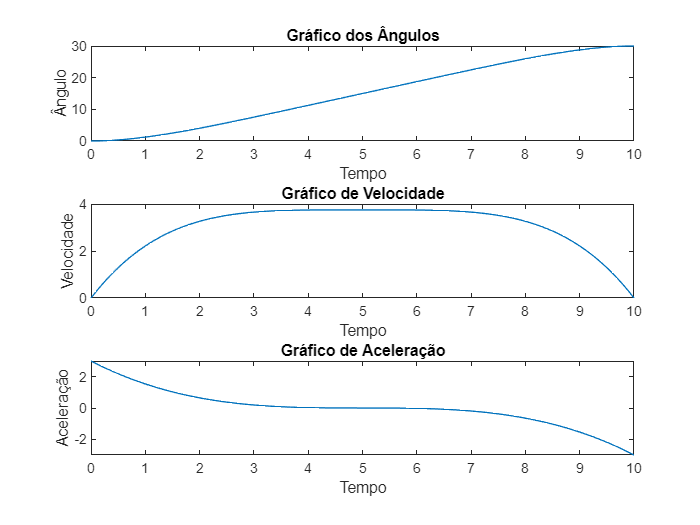

graf5ordPosVelAcel(M,10)

M = coef5(0,10,10,5)

M =          0
         0
    2.5000
   -0.9000
    0.1100
   -0.0044


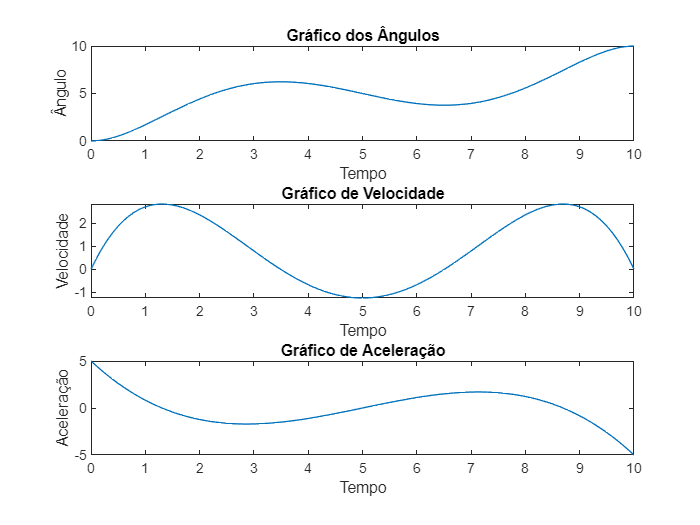

graf5ordPosVelAcel(M,10)